# 1.Familiar with Qunatization Function

I = imread("peppers.png");
help quant ;

 quant Discretize NN data as multiples of a quantity.
 
   quant(X,Q) quantizes NN data X so that all values are a replaced
   by the closest multiple of Q.  If Q is not supplied all values
   are rounded the nearest integer (i.e. multiple of 1).
 
   Here data in matrix form is quantized as multiles of 0.1:
 
     x = [1.333 4.756 -3.897; 4.223 5.239 0.031];
     y = quant(x,0.1)
 
   Here random values in cell array form is are quantized to 0.5:
 
     x = nndata([1;2],3,4)
     y = quant(x)

    Documentation for quant



A = 0:255

A =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49



% create a step for matrix A (64 steps) 
step = 256/4

step = 64


% quantizes the NN data from matrix A all values are replaced by 
% closest multiple of step
QA1 = quant(A, step)

QA1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    64    64    64    64    64    64    64    64    64    64    64    64    64    64    64    64    64    64



% create a partition matrix 
partition = step:step:256-step

partition =     64   128   192



% create a codebook matrix start from half of partition and
% end also half of partition
codebook = step/2:step:256-step/2

codebook =     32    96   160   224



%%---help quantiz
% create quantization index and quantize output value
% codebook prescribe the value for each partition in the qunatization 

% the quants QA2 contains the quantization of sig A based on quantization 
% levels and prescribe value.

%quants QA2 is a row vector same lengths as sig A.

% quants is related to indx and codebook as:
% quants(ii) = codebook(index(ii)+1)
% ii is integer 1<=  ii <=length(sig A)
[indx,QA2] = quantiz(A, partition, codebook)

indx =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


QA2 =     32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32



%%-help unique;
% return a unique value in array in sorted order
uA = unique(QA1)

uA =      0    64   128   192   256


uB = unique(QA2)

uB =     32    96   160   224


## 2.Quantization

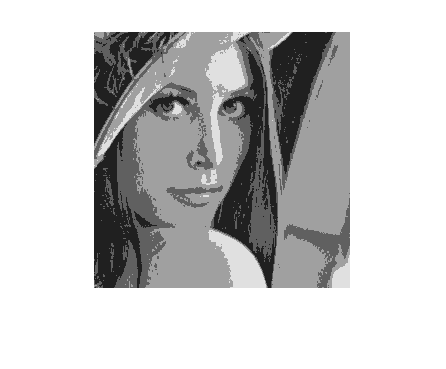

% a
%%--help reshape
lena = imread("lena_face.png");
lena = reshape(lena,[1,256*256]);

% 4-level
step1 = 256/4;
partition1 = step1:step1:length(lena)-step1;
codebook1 = step1/2:step1:length(lena)-step1/2;
[indx1,lena_q4] = quantiz(lena,partition1,codebook1); 

lena_q4 = uint8(reshape(lena_q4,[256,256]));
imshow(lena_q4)

u1 = unique(lena_q4)

u1 = 4×1 uint8 column vector
    32
    96
   160
   224


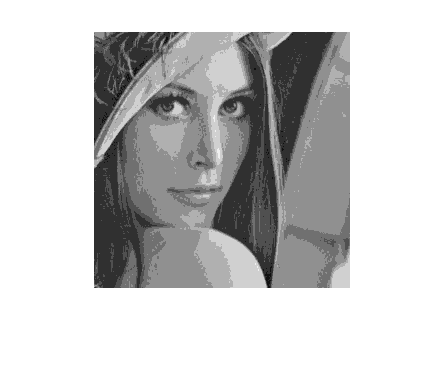


% 8-level
step2 = 256/8;
partition2 = step2:step2:length(lena)-step2;
codebook2 = step2/2:step2:length(lena)-step2/2;

[indx2,lena_q8] = quantiz(lena,partition2,codebook2); 
lena_q8 = uint8(reshape(lena_q8,[256,256]));
imshow(lena_q8)

u2 = unique(lena_q8)

u2 = 8×1 uint8 column vector
    16
    48
    80
   112
   144
   176
   208
   240


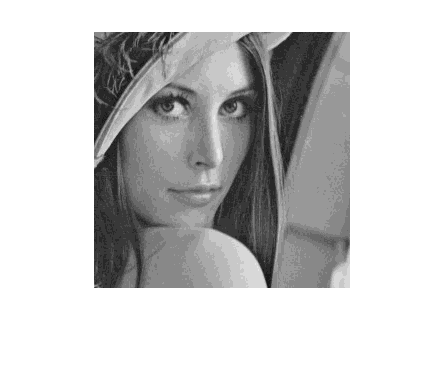


% 16-level
step3 = 256/16;
partition3 = step3:step3:length(lena)-step3;
codebook3 = step3/2:step3:length(lena)-step3/2;
[indx3,lena_q16] = quantiz(lena,partition3,codebook3); 
lena_q16 = uint8(reshape(lena_q16,[256,256]));
imshow(lena_q16)

u3 = unique(lena_q16)

u3 = 14×1 uint8 column vector
    24
    40
    56
    72
    88
   104
   120
   136
   152
   168


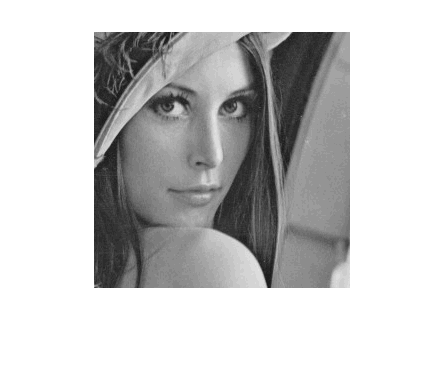


% 32-level
step4 = 256/32;
partition4 = step4:step4:length(lena)-step4;
codebook4 = step4/2:step4:length(lena)-step4/2;
[indx4,lena_q32] = quantiz(lena,partition4,codebook4);
lena_q32 = uint8(reshape(lena_q32,[256,256]));
imshow(lena_q32)

u4 = unique(lena_q32)

u4 = 27×1 uint8 column vector
   20
   28
   36
   44
   52
   60
   68
   76
   84
   92


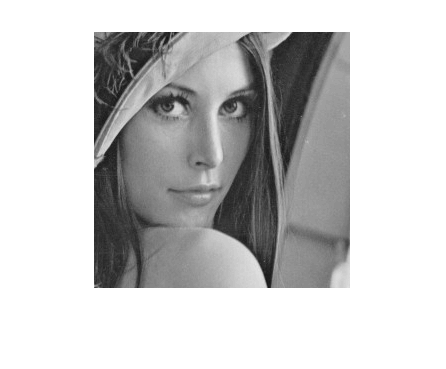


% 64-level
step5 = 256/64;
partition5 = step5:step5:length(lena)-step5;
codebook5 = step5/2:step5:length(lena)-step5/2;
[indx5,lena_q64] = quantiz(lena,partition5,codebook5); 
lena_q64 = uint8(reshape(lena_q64,[256,256]));
imshow(lena_q64)

u5 = unique(lena_q64)

u5 = 53×1 uint8 column vector
   22
   26
   30
   34
   38
   42
   46
   50
   54
   58


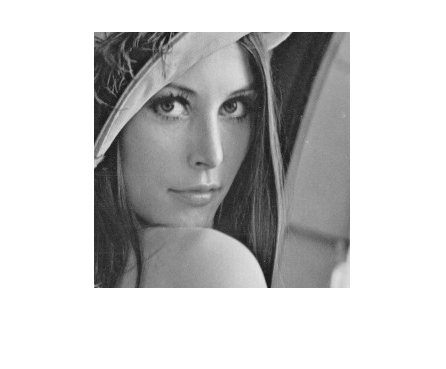


% 128-level
step6 = 256/128;
partition6 = step6:step6:length(lena)-step6;
codebook6 = step6/2:step6:length(lena)-step6/2;
[indx6,lena_q128] = quantiz(lena,partition6,codebook6); 
lena_q128 = uint8(reshape(lena_q128,[256,256]));
imshow(lena_q128)

u6 = unique(lena_q128)

u6 = 106×1 uint8 column vector
   21
   23
   25
   27
   29
   31
   33
   35
   37
   39


% b
ran_ = uint8(randn(1,256*256));
%lena_new = lena + ran_ ;
lena_new = lena + ran_*10

lena_new = 1×65536 uint8 row vector
   138   126   145   128    87   114   117   129   123   110   100   116   105   113   119    76    60    75    81    73    72    76    60    63    49    50    42    49    48    46    47    37    39    42    47    59    64    76    63    49    46    70    49    46    60    90   108    98    55    75


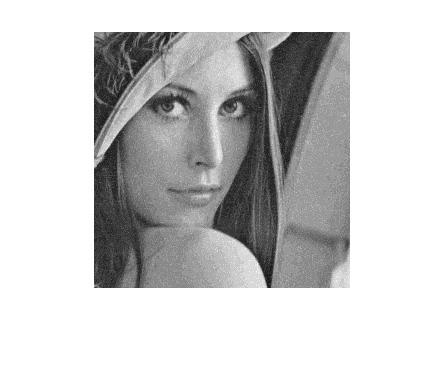

[index3_b,lena_q16_b] = quantiz(lena_new,partition3,codebook3);

%compare result
%lena_q16
lena_q16_b = uint8(reshape(lena_q16_b,[256,256]));
imshow(lena_q16_b)

% Add the noise
imshow(lena_q16 )


%NOTE:mages read by imread() are often data class uint8(). 
% The uint8() property will be retained in the rgb2gray() step. 
% Your saturation assignments of 0 and 1 are, however, based upon the notion that the minimum and maximum are 0 and 1 instead of 0 and 255.
% Also, the minimum value that a uint8 variable can be is 0, so there is no need to explicitly set 0 as the minimum.

## 3.Silmutaneous Constrast

help ones

 ones   Ones array.
    ones(N) is an N-by-N matrix of ones.
 
    ones(M,N) or ones([M,N]) is an M-by-N matrix of ones.
 
    ones(M,N,P,...) or ones([M N P ...]) is an M-by-N-by-P-by-... array of
    ones.
 
    ones(SIZE(A)) is the same size as A and all ones.
 
    ones with no arguments is the scalar 1.
 
    ones(..., CLASSNAME) is an array of ones of class specified by the 
    string CLASSNAME.
 
    ones(..., 'like', Y) is an array of ones with the same data type, sparsity,
    and complexity (real or complex) as the numeric variable Y.
 
    Note: The size inputs M, N, and P... should be nonnegative integers. 
    Negative integers are treated as 0.
 
    Example:
       x = ones(2,3,'int8');
 
    See also eye, zeros.

    

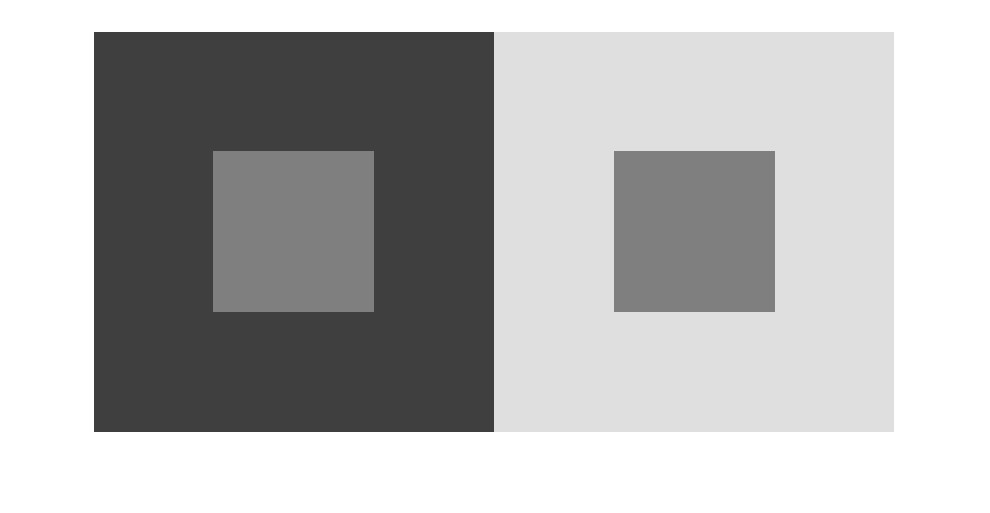

im=double(zeros(400,800));

%The left square 
im(1:400,1:800)=63/256;

%The right square
im(1:400,401:800)=223/256;
%im1=im(400,400);

%Indicate the middle left center square
im(120:120+160,120:120+160) = 127/256;

%Indicate the middle right square
im(120:120+160,401+120:401+120+160)=127/256;
imshow(im)


% the difference is due to the dependence the background
% I have choose the value 195 for the middle right square one:
%%--im(120:120+160,401+120:401+120+160)=195/256;